# Codificación MPEG. Estimación de Movimiento

Práctica. Procesado de Señal en Comunicaciones y Audiovisuales. Máster Universitario en Ingeniería de Telecomunicación

## Objetivo.

El propósito  de la práctica es implementar el procesado necesario para aprovechar la redundancia temporal de una secuencia de vídeo y poder aumentar así el ratio de compresión o mejorar la calidad de imagen manteniendo el régimen binario.  En general hay un primer paso de estimación de movimiento y un segundo paso de utilizar la estimación como una mejor predicción y así tener una residuo diferencial menor. 

 En el caso de estimación de movimiento para compresión, dicha estimación se realiza en cada zona local de la imagen, habitualmente macrobloques de 16x16 pixels.

Otro objetivo importante es familiarizarse con algunas de las herramientas que facilita Matlab para el proceso de imagen y vídeo. Por ello, es importante que, a medida que aparecen en la práctica, se consulte la ayuda de Matlab en su web para comprender mejor su funcionamiento y el alcance de sus capacidades, observando con atención la información suministrada online sobre su forma básica de uso así como de otros parámetros que admita la función y que puedan ser de interés en otros momentos. 

Algunas tareas necesarias en esta práctica, pero que no son expresamente de la codificación, se suministran en el guión para agilizar el tiempo de desarrollo, pero en otras ocasiones no se facilitan para que el alumno desarrolle su destreza en el uso del toolbox de imágenes y vídeo de Matlab.

Puede ser útil la siguiente forma de búsqueda a través de las palabras: matlab help ref concepto. Esto nos lleva casi siempre a tener como primer resultado la página de Mathworks con la información más interesante. Como concepto podemos utilizar el nombre de la función si la sabemos o, si no sabemos cómo se llama lo que nos conviene, ponemos alguna palabra relacionada con el concepto o procedimiento que nos interese.

## Instrucciones

Sigue el guión de la práctica ejecutando el código que está en negro y, cuando se indique en el texto, realiza el código apropiado para la tarea que se solicita.

En los comentarios hay indicaciones para facilitar la realización y también nombres de variables aconsejados, de manera que todos utilicemos las mismas y sea más fácil ayudarnos en caso de ser necesario y para la evaluación.

A lo largo del guión se hace referencia a párrafos anteriores. En esos casos se utilizará la notación (---- X ----), donde X es un número para indicar el punto al que se quiere referir.

## 1.- Cargar las imágenes

Vamos a tomar dos fotogramas CONSECUTIVOS de una secuencia, por ejemplo de la primera escena de la película El Padrino, Francis Ford Copola (1972), [https://www.youtube.com/watch?v=zjZAd041vpY.](https://www.youtube.com/watch?v=zjZAd041vpY.) 

Antes de comenzar con el siguiente código, reproduce algunos segundos de la secuencia del link previo  para tener un contexto de dónde se está produciendo el movimiento.

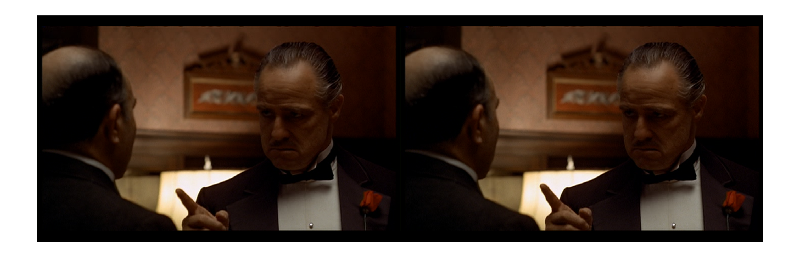


im1=imread('Padrino_frame1.png');
im2=imread('Padrino_frame2.png');
figure, imshow([im2, im1])

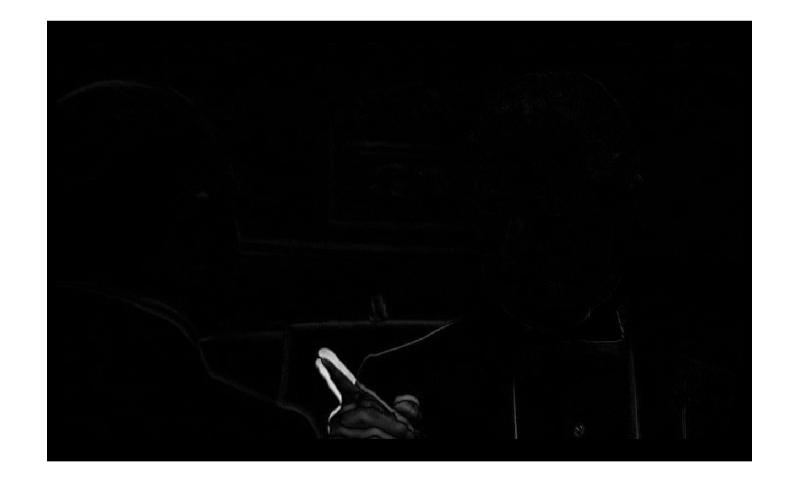

% veamos las diferencias de sus niveles de gris
im1G=rgb2gray(im1);
im2G=rgb2gray(im2);
im1Gd=double(im1G); %convertimos a double para poder operar con valores negativos en la resta
im2Gd=double(im2G);
imDif = uint8(abs(im2Gd-im1Gd)); %convertimos a uint8 para que imshow visualice correctamente el rando 0-255
figure, imshow(imDif)

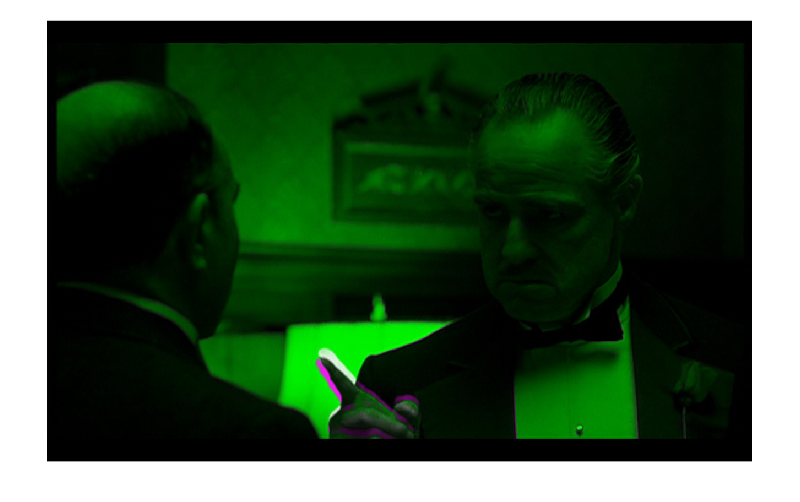

% la diferencia sobreimpresa
figure, imshowpair(im2,imDif,'falsecolor')

Como en H26x y MPEG la forma fundamental de estimación de movimiento es a base de macrobloques de 16x16, vamos a sobreimprimir una rejilla de ese tamaño.

Utilizaremos la función insertShape. Consulta la ayuda online para entender la sintaxis.  

Como nombres de las imágenes resultantes utilizamos el sufijo Mblocks.  (MBlocks de la palabra Macrobloque)

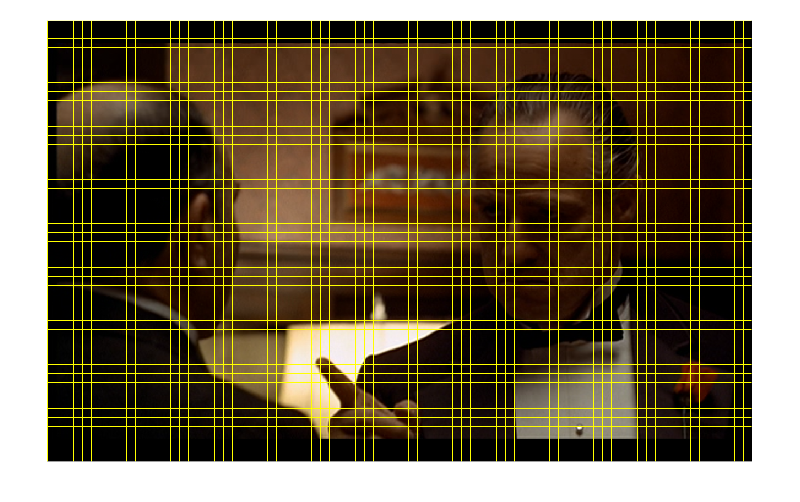

% lineas verticales cada 16 pixels
% 
[nRows, nCols, nColors]=size(im2);

posVert =1:16:nCols;     %posiciones de las lineas verticales
nMblocksH = length(posVert);  % numero de lineas verticales es igual al numero de macrobloques en horizontal

% Vamos a contruir la matriz que necesita la funcion insertShape con la
% info de todas las lineas verticales que queremos dibujar

% line endpoints, a matrix with 4 columns and the number of rows equal to
% the number of lines
vertLines = zeros(nMblocksH,4);
% cada fila es una línea [x1 y1 x2 y2]. En las verticales todas comienzan con  y1 a cero (1 en
% matlab), y todas terminan en la última fila  (nRows). Como son verticales x1 = x2;
vertLines(:,1)=posVert;
vertLines(:,3)=posVert;
vertLines(:,2)=1;
vertLines(:,4)=nRows;
im2Mblocks = insertShape(im2,'Line',vertLines,'LineWidth',1);


%hacemos lo mismo para las lineas horizontales
% horz lines
posHorz =1:16:nRows;
nMblocksV = length(posHorz);

horzLines = zeros(nMblocksV,4);
% each row is a line, [x1 y1 x2 y2]. Every y1 is zero (one in
% matlab), every y2 is nRows, x1 = x2;
horzLines(:,1)=1;
horzLines(:,2)=posHorz; 
horzLines(:,3)=nCols;
horzLines(:,4)=posHorz;

im2Mblocks = insertShape(im2Mblocks,'Line',horzLines,'LineWidth',1);
figure, imshow(im2Mblocks)

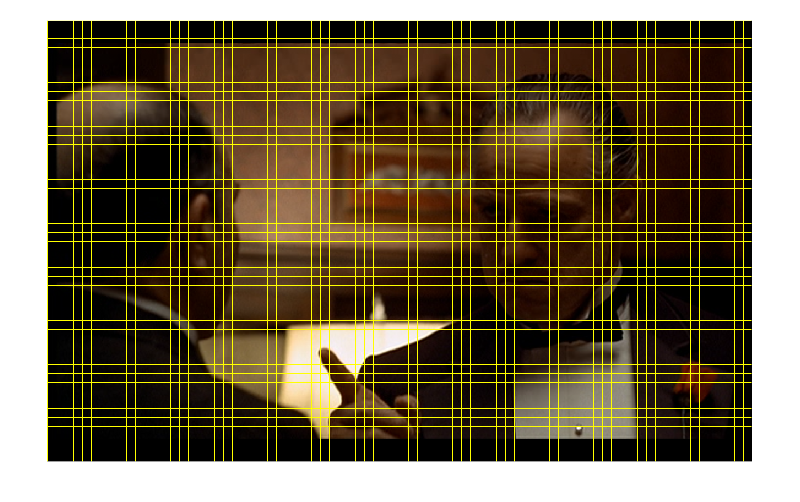

im1Mblocks = insertShape(im1,'Line',vertLines,'LineWidth',1);
im1Mblocks = insertShape(im1Mblocks,'Line',horzLines,'LineWidth',1);
figure, imshow(im1Mblocks)

La estimación de movimiento se hace para cada uno de los macrobloques de la imagen ACTUAL por turno en orden 'raster'. 

En estos apartados  vamos a hacerlo para uno sólo de ellos. El proceso es el mismo para todos los demás

Vamos a suponer que le toca el turno a la zona del dedo.

Utilizamos el adjetivo  "actual" para referirnos al macrobloque o a la imagen que se está codificando en ese momento y  la expresión  "de referencia"  para referirnos a la imagen  en la que se busca donde está ese mismo contenido del macrobloque actual (generalmente es una imagen pasada, pero en ocasiones puede ser una imagen posterior en el tiempo)

En este caso vamos a suponer que le toca el turno al macrobloque de la fila 31 y la columna 39 (filas y columnas de macrobloques, no de pixels).

y buscaremos ese contenido en la imagen1 tomándola como imagen de referencia. 

Sobreimprimimos una cruz roja en la esquina superior izquierda de ese macrobloque para ayudar a verlo.  La salida la nombramos con el sufijo bV_bH

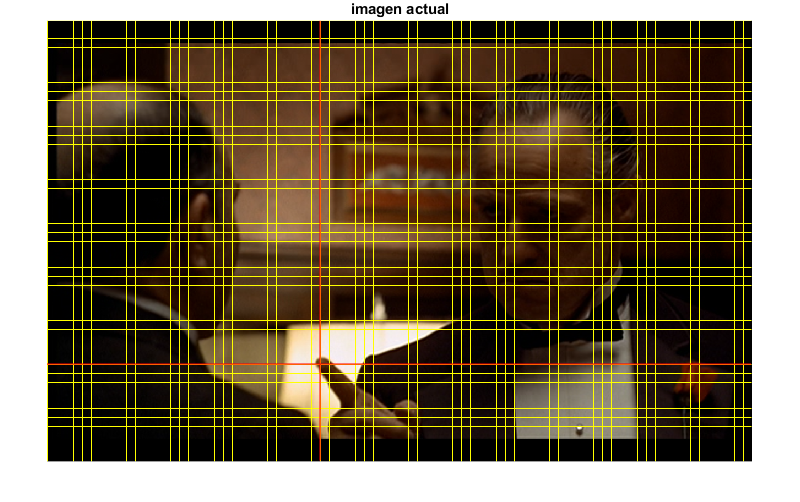


bH = 31;
bV = 39;
linesbH_bV = [bH*16+1, 1, bH*16+1, nRows; 1,bV*16+1, nCols,bV*16+1];
im2MblocksbV_bH = insertShape(im2Mblocks,'Line',linesbH_bV,'LineWidth',2, "Color","red");
figure, imshow(im2MblocksbV_bH), title('imagen actual')

Para que se vea bien la diferencia de posicion de ese contenido entre la im2 y la im1 dibujamos las lineas rojas 

en im1 en LAS MISMAS COORDENADAS que en im2. 

Observa con precisión la diferencia de posición de dedo. El movimiento es hacia el suelo porque en la imagen 1 está más alto que en la imagen 2, que es posterior.

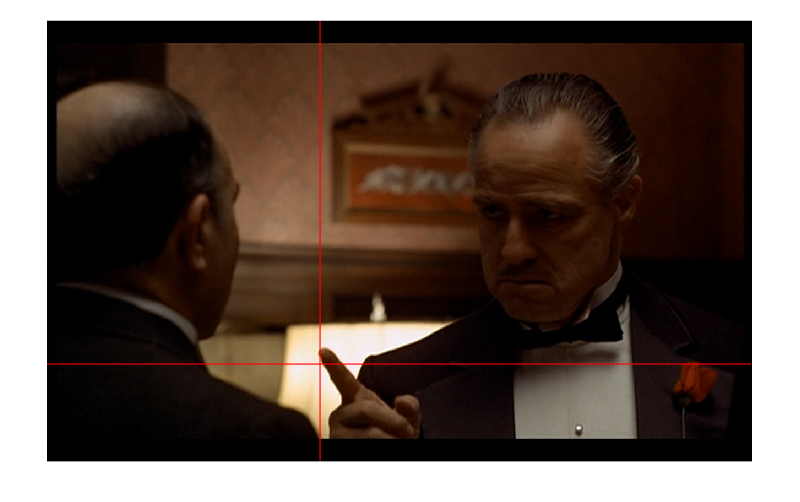


im1CruzbV_bH = insertShape(im1,'Line',linesbH_bV,'LineWidth',2, "Color","red");
figure, imshow(im1CruzbV_bH)

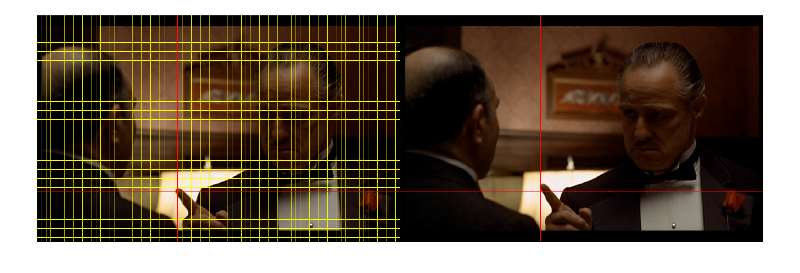

%dibujamos una al lado de la otra para comparar mejor.

%OBSERVA LA DIFERENCIA DE POSICION DEL DEDO

figure, imshow([im2MblocksbV_bH im1CruzbV_bH])

## Estimación de movimiento.

### Cálculo del error cuadrático medio entre dos matrices.

Realiza una función que, dadas dos matrices, calcule el error cuadrático medio. LLámala errorc.m y guárdala en un fichero errorc.m de la carpeta de trabajo. 

Debe funcionar  cuando las dos matrices son bidimensionales y también cuando  las dos matrices son tridimensionales (imagen en color). 

 Vamos a utilizarla. Extrae el bloque que comienza en la esquina de las líneas rojas en la imagen 2 con el código que hay a continuación. Lo llamamos Mblock2. 

Completa el código y calcula el error cuadrático medio entre los bloques Mblock2 y el bloque correspondiente en las mismas coordenadas en la imagen1. 

Comprueba que el resultado es: 158.75  

(---- 1 ----)


% (---- 3 ----)
Mblock2 = im2(bV*16+1 : (bV+1)*16, bH*16+1 : (bH+1)*16, : );
Mblock1 = im1(bV*16+1 : (bV+1)*16, bH*16+1 : (bH+1)*16, : );
errB2B1= errorc(Mblock1, Mblock2)

errB2B1 = 158.7514

Con la función imresize(im,Z), crea una versión aumentada de tamaño xZ, (tomamos Z=8, por ejemplo) de cada uno de los dos bloques y de la diferencia. 

Para que los valores negativos de la diferencia se puedan apreciar (el rango del resultado va de -255 a + 255), la imagen se reescala dividiéndola por dos y sumándole 128, de manera que una diferencia original de cero se verá en la imagen como  un valor de 128 en cada componente.

Visualizamos las tres, una al lado de la otra, para ver bien las diferencias. Pon título en cada imagen. 

Cuidado con el formato de datos al calcular la diferencia ya que, el formato uint8 por defecto de las imágenes no puede albergar resultado negativo. 

Hay que convertir a double antes de hacer la resta, pero luego, para visualizar correctamente el rango 0 a 255, hay que volver a convertir a uint8.

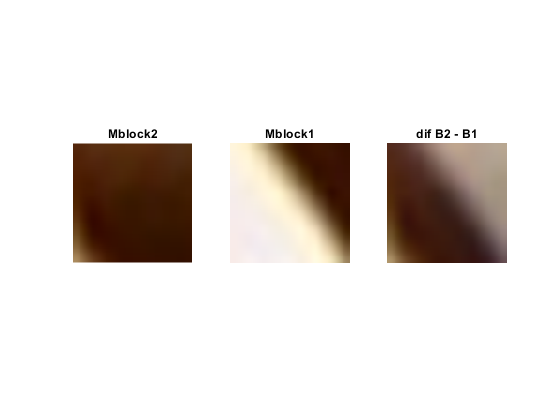

% para que se vea un poco mas grande hacemos zoom x8:

%DESCOMENTA EL CODIGO Y EJECUTA
 zz = 8;
 figure, 
 subplot(131), imshow(imresize(Mblock2,zz)), title('Mblock2')
 subplot(132), imshow(imresize(Mblock1,zz)), title('Mblock1')
 subplot(133), 
 difB2B1 = uint8(floor((double(Mblock2)-double(Mblock1)/2)) +128 );
 imshow(imresize(difB2B1,zz)), title('dif B2 - B1')

En la mayoría de las ocasiones, la estimación de moviento se hace sobre la componente de luminancia (niveles de gris) de las imágenes porque da resultados similares pero ocupa la tercera parte de operciones. Realiza las operaciones de la sección  previa pero en niveles de gris. Comprueba que el error cuadrático medio es 158.47.

% BEGIN ALUMNO
Mblock2Gray = rgb2gray(Mblock2);
Mblock1Gray = rgb2gray(Mblock1);
errB2B1Gray= errorc(Mblock1Gray,Mblock2Gray)

errB2B1Gray = 158.4652

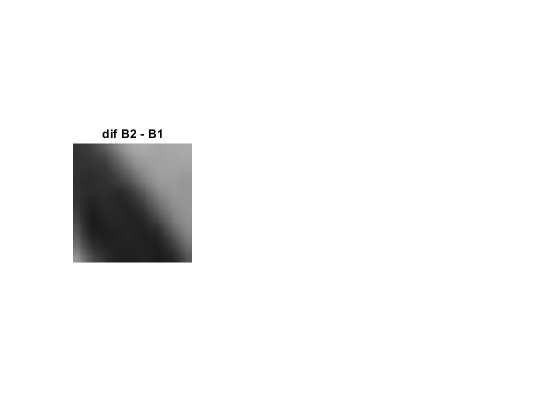

% 
 figure, 
 subplot(131), imshow(imresize(Mblock2Gray,zz)), title('Mblock2Gray');
 difB2B1Gray = uint8(floor((double(Mblock2Gray)-double(Mblock1Gray)/2))+128);
 imshow(imresize(difB2B1Gray,zz)), title('dif B2 - B1');

### Localización de la posición con el mínimo error cuadrático medio.

Ahora se trata de mover PIXEL A PIXEL una ventana de observación en la imagen de referencia (im1) por el área de búsqueda centrada en la coordenada inicial del bloque de la imagen actual (im2) y localizar la posición donde el error cuadrático medio es el mínimo.

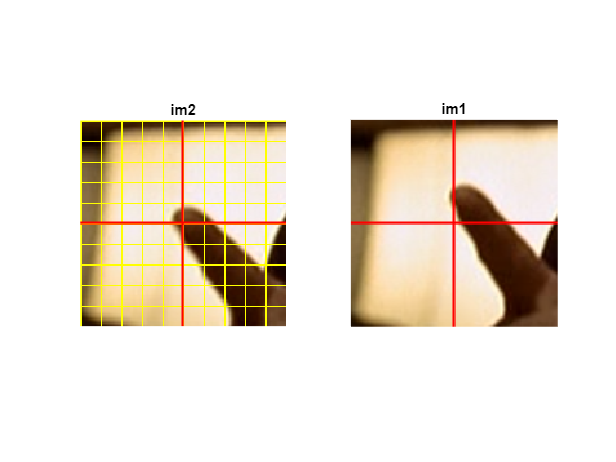

% para que se vea mejor el problema a resolver, mostramos solo el entorno en ambas imagenes
%  por ejemplo 5 bloques antes y despues del bloque de interes

nn=5;
xIni= (bH - nn)*16+1;
xFin= (bH + nn)*16;
yIni= (bV - nn)*16+1;
yFin= (bV + nn)*16;


%(---- 2 ----)

subIm2 = im2MblocksbV_bH(yIni:yFin,xIni:xFin,:);
subIm1 = im1CruzbV_bH(yIni:yFin,xIni:xFin,:);

figure, 
subplot(121),imshow(subIm2),title('im2')
subplot(122),imshow(subIm1),title('im1')

Realiza una función llamada exhaustiva.m y guárdala en un fichero exhaustiva.m de la carpeta de trabajo. El primer parámetro será el bloque de interés de la imagen actual, en nuestro caso Mblock2.

El segundo parámetro será la imagen de referencia. Los siguientes serán, respectivamente, el índice horizontal en unidades de pixel (la columna) y vertical (la fila) en la imagen actual que ocupa el primer pixel de Mblock2 en dicha imagen actual (el primer pixel de la imagen sería el índice 1). 

Esto se necesita para saber dónde hay que centrar la búsqueda en la imagen de referencia. 

Finalmente se suministrará el desplazamiento máximo permitido para la búsqueda, llamado despmax. 

Se implementará un área de búsqueda cuadrada tal que la esquina superior izquierda de la ventana de observación se desplace despmax hacia la izquierda, despmax hacia la derecha, despmax hacia arriba y despmax hacia abajo. El resultado serán tres valores, primero el desplazamiento en horizontal y vertical respecto de la posición inicial de la búsqueda donde se ha encontrado la mínima diferencia. 

El tercer resultado será dicha diferencia.  

Haz una llamada a la función con un despmax = 40. Llama al resultado [vx, vy, errMin].

Comprueba que el vector de momiento resultantes es vx = 3; vy= -18 y el error es errMin = 4.86

[vx,vy, errMin] = exhaustiva(Mblock2 ,im1, bH*16+1, bV*16+1  , 40)

vx = 3

vy = -18

errMin = 4.8623

Observa que en la sección anterior (---- 1 ----) cuando se ha calculado la diferencia entre los macrobloques sin tener en cuenta el movimiento, el resultado ha sido un error cuadrático medio de 158.75, mientras que ahora es de 4.86.

Se ha conseguido reducir mucho gracias a buscar dónde se encuentra el contenido más parecido y hacer la diferencia respecto a él.

Dibuja una cruz, similar a las utilizadas anteriormente pero ahora de color AZUL, en la posición encontrada para la ventana de observación que minimiza la diferencia sobre la imagen de referencia (im1).

A la imagen con la cruz AZUL llámala im1CruzbV_bH_MotionCompensated

linesbH_bV_MotionCompensated = [bH*16+1 + vx, 1, bH*16+1 + vx, nRows; 1 , bV*16+1 + vy, nCols, bV*16+1 + vy]                               %matriz con dos filas de cuatro valores. Cada fila son las coordenadas de una recta de las dos rectas de la cruz

linesbH_bV_MotionCompensated =          500           1         500         800
           1         607        1280         607


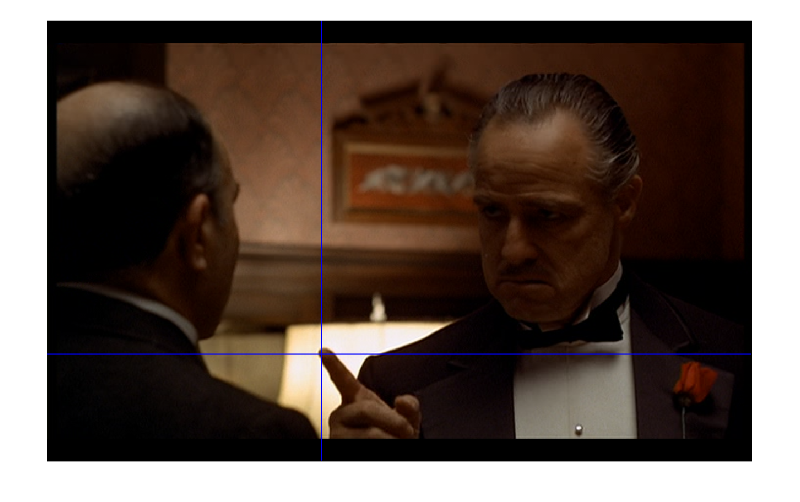

im1CruzbV_bH_MotionCompensated  =  insertShape(im1, 'Line', linesbH_bV_MotionCompensated, 'LineWidth', 2, 'Color','blue');                   % insertShape
figure, imshow(im1CruzbV_bH_MotionCompensated)

Extrae, de la misma manera que antes (---- 2 ----), la subimagen de MotionCompensated en el rango xIni-xFin yIni-yFin calculados previamente, y visualiza las tres (subIm2, subIm1, subIm1_MC ) para comparar

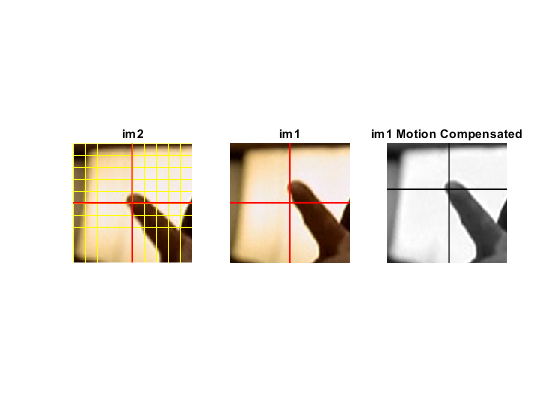

 subIm1_MC = im1CruzbV_bH_MotionCompensated(yIni:yFin, xIni:xFin);
 figure,
 subplot(131),imshow(subIm2),title('im2')
 subplot(132), imshow(subIm1), title('im1')
 subplot(133),imshow(subIm1_MC),title('im1 Motion Compensated')

Calcula con la función exhaustiva el vector de movimiento para la versión de grises de Mblock2 e im1. 

Observa que el resultado del vector es el mismo que con el cálculo en color. No siempre ocurre así, pero el grado de parecido es suficientemente alto para que valga la pena el ahorro de coste computacional.

[vxGray,vyGray, errMinGray] = exhaustiva(rgb2gray(Mblock2), rgb2gray(im1), bH*16+1, bV*16+1, 40)

vxGray = 3

vyGray = -18

errMinGray = 4.4335

## Codificación de las diferencias

En MPEG/H26x se transmite la diferencia respecto al contenido compensado en movimiento. 

Muestra, de forma similar a como se ha hecho al principio de la sección "Cálculo del error cuadrático medio entre dos matrices" (copia, pega el código y adáptalo) (---- 3 ----), los siguientes cuatro contenidos:

1.- El macrobloque en curso, bock2;

2.- El área de tamaño 16x16 encontrada como referencia (la que minimiza la diferencia) para el Mblock2. Llámalo Mblock1MC.

3.- El valor absoluto de la diferencia entre bock2 y Mblock1MC (cuidado con el formato uint8). Llámale absDifMC. 

4.- A efectos comparativos muestra la absDif entre Mblock2 y Mblock1. 

Observa cómo absDifMC es prácticamente negro mientras que si no hay compensación de movimiento los valores son bastante más altos. 

A efectos de que se pueda comprobar si se ha calculado correctamente absDifMC, la operación mean(absDifMC(:)) da: 3.46

 Mblock1MC = im1(bV*16+1 + vy : (bV+1)*16 + vy, bH*16+1 + vx: (bH+1)*16 + vx, :);
 
 figure, 
 subplot(141), imshow(imresize(Mblock2,8)), title('im2');
 absDifMC = abs(double(Mblock1MC) - double(Mblock2));
 meanAbsDifMC = mean(absDifMC(:))

meanAbsDifMC = 3.4596

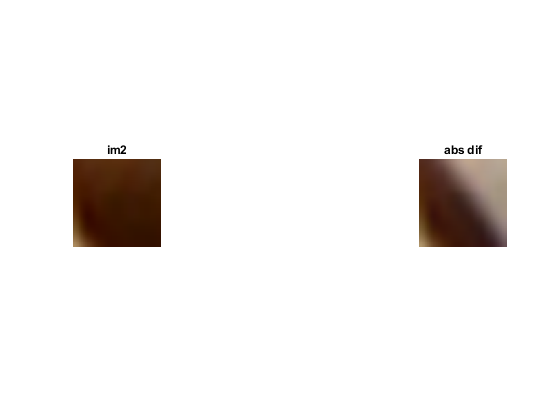

 subplot(144), imshow(imresize(difB2B1,8)), title('abs dif');

## Impacto en los coeficientes cuantificados a transmitir.

Vamos a realizar los primeros pasos de la codificación de los coeficientes mediante el proceso baseline con la transformada discreta del coseno para ver la diferencia entre la información a transmitir utilizando o sin utilizar compensación de movimiento.

De los cuatro bloques de 8x8 que tiene un macrobloque de 16x16, llamémosles por ejemplo  con los sufijos de su fila y columna, 11, 12, 21, 22,  lo vamos a realizar sólo sobre el primero, B11.

De las tres componentes (Y, Cb, Cr) que tiene cada bloque lo vamos a realizar sólo sobre la componente de luminancia.

Los pasos serán

1.- Extreer de los macrobloques 2 y 1MC el bloque 11.  Les nombramos b2_11 y b1MC_11

2.- Calcular la luminancia y pasarlos a double para poder operar correctamente

3.- Restarlos. A continuación, pasar del rango -255 a +255 al rango -128 a +127, dividimos por dos y aplicamos la función floor. Al resultado le llamamos bDifMC

4.- Calculamos la DCT bidimensional con la función dct2. Le llamamos bDctMC

5.- Dividimos (PUNTO A  PUNTO) por la tabla de cuantificación estándard para la luminancia qty y nos quedamos con la parte entera con la función round. Llamamos al resultado bDctMCq

6.- Para obtener los coeficientes en el caso sin compensación de movimiento, repetimos los 5 pasos pero utilizando los macrobloques 2 y el 1 (sin compensación de movimiento)

Observa que en el caso de la compensación de movimiento son todo ceros, salvo un valor a -1, mientras que sin compensación de 

de momiviento hay que transmitir 11 coeficientes y de valores bastante más grandes.

qty=[
    16    11    10    16    24    40    51    61;
    12    12    14    19    26    58    60    55;
    14    13    16    24    40    57    69    56;
    14    17    22    29    51    87    80    62;
    18    22    37    56    68   109   103    77;
    24    35    55    64    81   104   113    92;
    49    64    78    87   103   121   120   101;
    72    92    95    98   112   100   103    99];   
     
 b2_11Gray = double(rgb2gray(Mblock2(1:8, 1:8, :)));
 b1MC_11Gray = double(rgb2gray(Mblock1MC(1:8, 1:8, :)));
 bDifMC = floor((b2_11Gray - b1MC_11Gray)/2);
 bDctMCq = dct2(bDifMC);
 
 b1_11Gray = round(bDctMCq./qty);

## Estimación para seguimiento del movimiento.

Vamos a aplicar ahora la estimación de movimiento para realizar el seguimiento de la trayectoria de un punto a lo largo del tiempo en una secuencia de vídeo.

Graba con la cámara del teléfono móvil una secuencia de las siguientes características:

 (LEE TODAS LAS INSTRUCCIONES Y MIRA LA SIGUIENTE IMAGEN  ANTES DE COMENZAR A GRABAR) 

Pon el móvil en modo grabación de vídeo y cógelo con la mano que no utilizas para escribir.

Deja la mano con la que escribes sobre la mesa con el puño cerrado. 

A continuación, extiende sólo el dedo índice para que la punta toque la superficie de la mesa y el dedo quede bastante horizontal.

Con la otra  mano toma el móvil y encuadra la mano para que el extremo del dedo índice 

quede aproximadamente en el centro de la imagen y que la vista sea desde arriba, más o menos vertical.

Asegúrate de que no aparezca borrosa, dale tiempo a que el enfoque automático actúe. Procura que no haya sombras en el entorno de la mano.

Cuando sea el momento apropiado, inicia la grabación y, sin mover la cámara, realiza una desplazamiento con el dedo de forma similar a como si estuvieras escribiendo

la última cifra numérica de tu DNI, sin levantar el dedo y con una sola trayectoria, de manera que no haya saltos en el movimiento del dedo y, 

cuando finalices la trayectoria, deja el dedo quieto en ese punto y permanece grabando un segundo o dos más.

Asímismo, inicia la grabación un segundo o dos ANTES  de iniciar el movimiento del dedo. 

RECUERDA intentar manterner quieta la cámara durante TODA la grabación.

Ya puedes realizar la grabación.

Haz llegar el fichero  de vídeo por algún procedimiento al ordenador de trabajo (email, airdrop, carpeta compartida, etc.).

El ejercicio de este apartado consiste en realizar una función que, dado el vídeo y la coordenada inicial  a seguir, de como resultado una matriz que muestre la posición 

que la punta del dedo ha ocupado a lo largo del vídeo. En la matriz, cada fila serán los valores x,y de la posición detectada y tendrá tantas filas como frames tenga el vídeo. 

Se deberá realizar una segunda función que, dado el primer frame del vídeo y la matriz de posiciones obtenida, dibuje un círculo en cada una de ellas. 

El resultado será algo similar a la imagen mostrada a continuación.

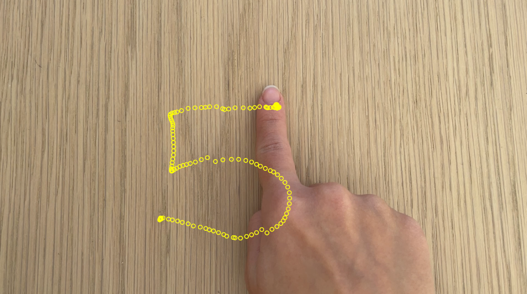

Para selecionar el punto a seguir, desde la ventana de comandos de matlab,  abre el video con VideoReader, 

lee el primer frame, crea una figura, muestra la imagen y, teclea impixelinfo. 

Muevete con el ratón a un punto donde se junte la uña con la piel del dedo.

En la parte inferior de la figura verás un texto con el color del pixel y las coordendas.

Tienes las instrucciones en la siguiente sección.

A la función de seguimiento, le llamaremos out = seguimiento('nombreVideo', xInicial,yInicial)

y a la función de dibujar los círculos imDisplay = overlay(imagenPrimera, out)

Realiza todo el proceso y muestra tu imagen resultante.

Los resultados a subir son:

-  el video grabado 

- las funciones  overlay.m

- seguimiento.m

- exhaustiva.m

- errorc.m

- este fichero mlx con el trabajo realizado

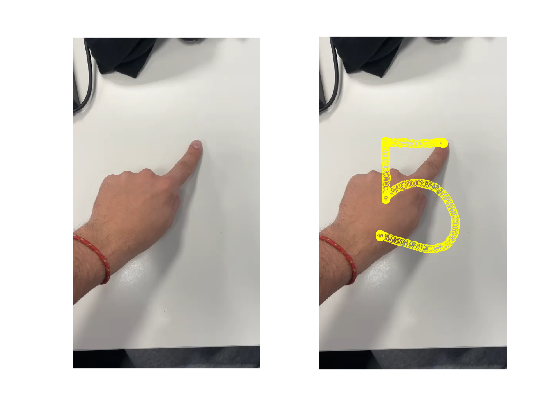

% instrucciones que pueden resultar de interes

 vid = VideoReader('video.mp4');     % para preparar la lectura frame a frame de un video
 img = read(vid,1);

 out = seguimiento('video.mp4', 320,272);

 imgF = overlay(img, out);

 figure, 
 subplot(121), title('Frame inicial'), imshow(img)
 subplot(122), title('Dibujo'), imshow(imgF)